# Getting Started with IMVIEW Image Display Function

The function `imview` displays a binary, grayscale, or RGB image. It is intended to be used instead of `imshow` in most cases. 

Unlike `imshow`, it does not resize the figure. It also uses the `"tight"` option for `XLimitMethod` and `YLimitMethod` instead of setting `XLim` and `YLim` manually. For these reasons, `imview` tends to behave better when used with other MATLAB graphics functions and capabilities. The function also uses a higher-quality image interpolation method, with antialiasing, by default.

## System Requirements

The function `imview` requires the following add-ons that are available from the MATLAB File Exchange:

- [Pixel Grid](https://www.mathworks.com/matlabcentral/fileexchange/71622-pixel-grid)

- [Image Zoom Level and Pan Utilities](https://www.mathworks.com/matlabcentral/fileexchange/167316-image-zoom-level-and-pan-utilities)

## Examples

### Display Binary Image

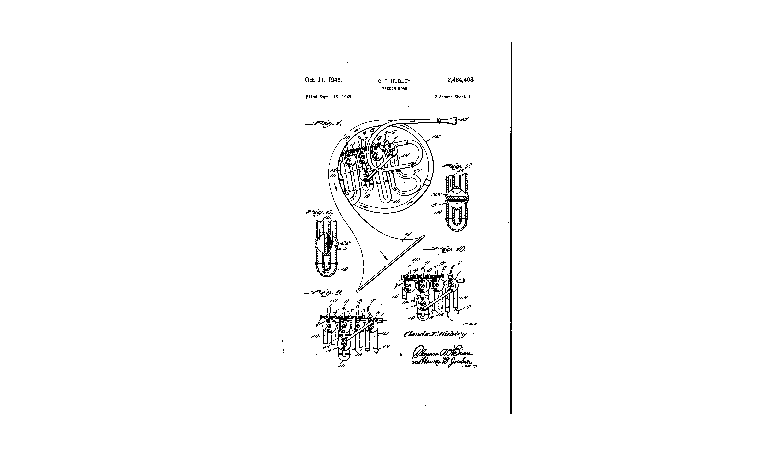

A = imread("US2484408-drawings-page-1.png");
imview(A)

### Display Grayscale Image

**Note**: When this example is viewed in the MATLAB Editor, the captured image may exhibit significant aliasing. This is apparently due to a limitation in the way that the Editor reduces the size of captured figures in the editor. It is not an artifact caused by `imview`.

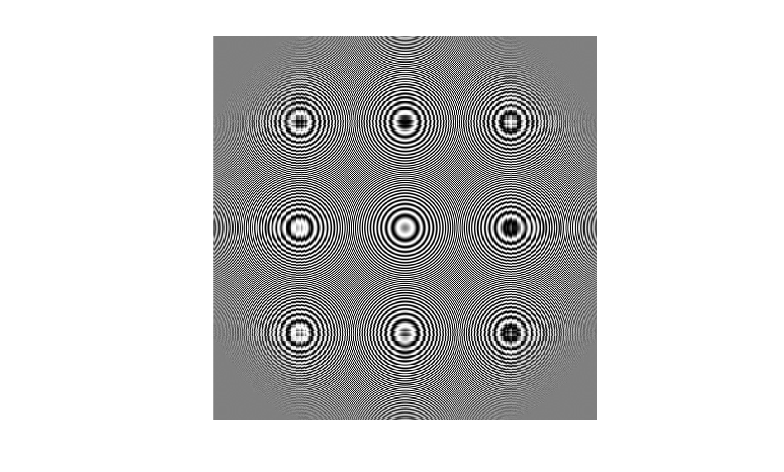

B = imread("zp2000.jpg");
imview(B)

### Display RGB Image

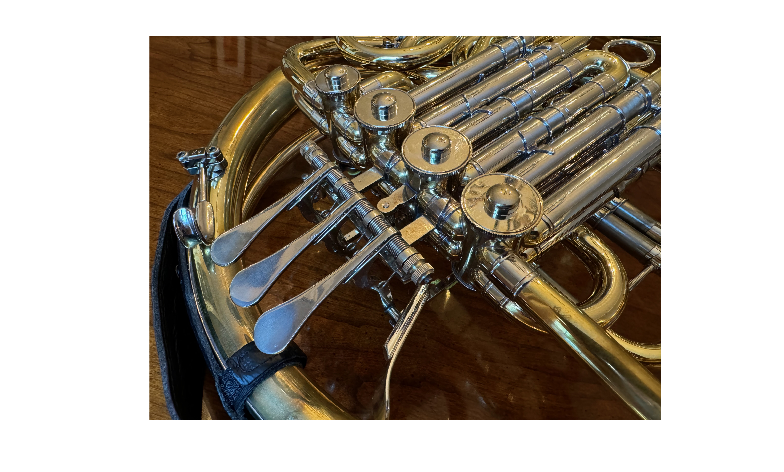

C = imread("horn.jpg");
imview(C)

### Display Image with Visible Axes

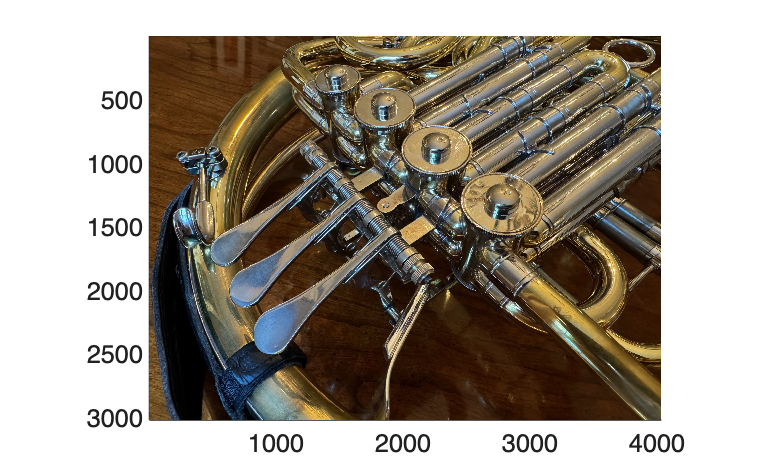

imview(C)
axis on

### Display Image and Plot New Data

Unlike `imshow`, the function `imview` does not prevent the axes object from automatically readjusting its limits to respond to additional plotted data. The axes does, however, continue to maintain a data aspect ratio of `[1 1 1]`.

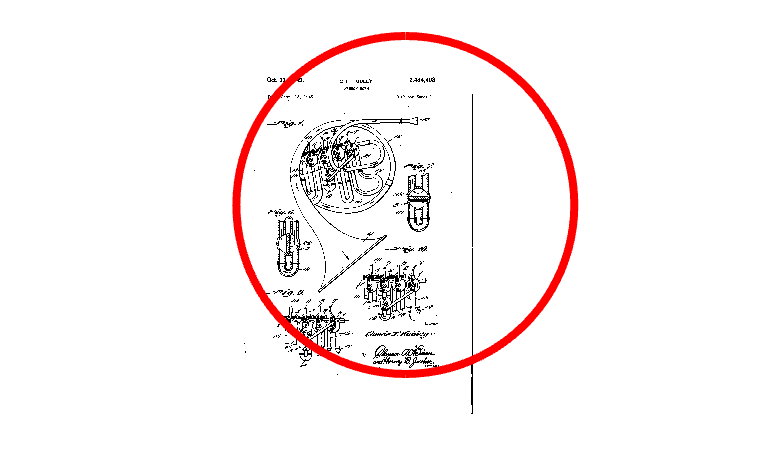

imview(A)
hold on
rectangle(Position = [0 0 3000 3000],...
    Curvature = [1 1],...
    EdgeColor = "red",...
    LineWidth = 3);
hold off

## Comparison with IMSHOW

Here are the specific differences between `imview` and `imshow`:

- `imview` does not resize the figure containing the image display. Instead, the image is displayed in the current axes in the current figure without changing the figure or axes size.

- `imview` displays the image using bilinear interpolation and antialiasing, unless individual pixels are larger than about 0.2 inches. In that case, the interpolation switches automatically to nearest neighbor, and a pixel grid is shown. The function `imshow` uses nearest neighbor interpolation by default.

- Unlike `imshow`, `imview` does not explicitly set the axes `XLim` and `YLim` properties. Instead, it sets the `XLimitMethod` and `YLimitMethod` properties to `"tight"`. With this choice, the axes limits will tightly enclose the data contained by the axes, including the image and anything else that might also be plotted in the same axes. Also unlike `imshow`, the axes limits will continue to automatically adjust to additional data being plotted there.

- `imview` does not observe the MATLAB Image Display Preferences.

## Limitations

The function `imview` is under development, and this is an early version. It does not yet have some of the optional behaviors supported by `imshow`, including:

- Overriding the default black-white range

- Overriding the default interpolation behavior

- Overriding the default `XData` and `YData`

- Setting the initial magnification level

- Specifying the parent axes

- Displaying an indexed image

- Using an image filename or URL

## Installation and Setup

Download the `.mltbx` file from the [GitHub repository releases area](https://github.com/eddins/imview/releases/)%20or%20from%20the%20[File%20Exchange). Double-click on the downloaded file to automatically and run the MATLAB add-on installer. This will copy the files to your MATLAB add-ons area and add the appropriate folder to your MATLAB search path.

After installation, this `imview` version may be shadowed by a placeholder function in Image Processing Toolbox with the same name. That function only issues an error message. It is a remnant of a general image display tool that existed in the product about 20 years ago. To fix this installation issue:

- Click "Set Path" in the MATLAB toolstrip. 

- Find the path entry for the IMVIEW add-on; it may be near the bottom of the long list. 

- Right-click on the path entry and select "Move to top." 

- Check the box that says "Save path for future sessions."

- Click "Apply."

Later, you can use the [MATLAB Add-On Manager](https://www.mathworks.com/help/matlab/matlab_env/get-add-ons.html) to uninstall.